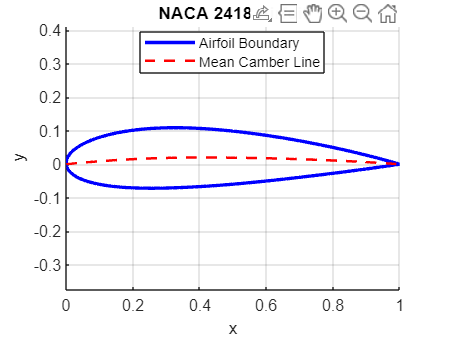

[xb, yb] = naca4_boundary('2418', 201, 1.0, 'cosine');

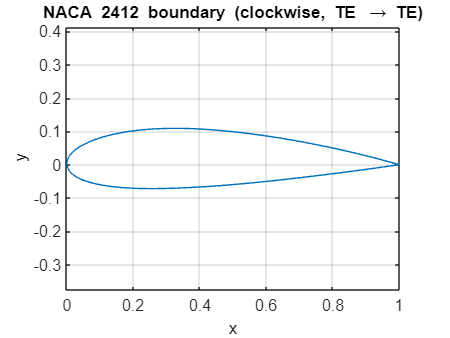


figure; plot(xb, yb, '-'); axis equal; grid on;
xlabel('x'); ylabel('y'); title('NACA 2412 boundary (clockwise, TE \rightarrow TE)');


%Sanity checks
fprintf('Total boundary points: %d\n', numel(xb));

Total boundary points: 400


fprintf('Start @ TE: (%.6f, %.6f)\n', xb(1), yb(1));

Start @ TE: (1.000000, -0.000000)


fprintf('End   @ TE: (%.6f, %.6f)\n', xb(end), yb(end));

End   @ TE: (0.999937, -0.000009)


function [xb, yb] = naca4_boundary(naca, N_per_side, c, spacing)
% NACA4_BOUNDARY  NACA 4-digit airfoil boundary points (clockwise, TE→...),
% with the trailing-edge point included ONCE (start only). Also plots the
% airfoil and mean camber line in different colors.
%
%   [xb, yb] = naca4_boundary(naca, N_per_side, c, spacing)

    if nargin < 4 || isempty(spacing), spacing = 'cosine'; end
    if nargin < 3 || isempty(c),       c = 1.0;            end
    if nargin < 2 || isempty(N_per_side), N_per_side = 101; end

    code = char(naca);
    assert(numel(code) == 4, 'naca must be a 4-character code like ''2412''.');
    m = str2double(code(1))   / 100;   % max camber
    p = str2double(code(2))   / 10;    % location of max camber
    t = str2double(code(3:4)) / 100;   % thickness ratio

    % ---- x distribution on [0,c] (LE at 0, TE at c) ----
    switch lower(spacing)
        case 'cosine'
            beta = linspace(0, pi, N_per_side).'; 
            x    = 0.5*c*(1 - cos(beta));    
        case 'linear'
            x    = linspace(0, c, N_per_side).';
        otherwise
            error('spacing must be ''cosine'' or ''linear''.');
    end
    xi = x / c;

    % ---- thickness distribution (closed TE: -0.1036) ----
    yt = (t*c/0.2) .* ( 0.2969*sqrt(xi) - 0.1260*xi - 0.3516*xi.^2 ...
                        + 0.2843*xi.^3 - 0.1036*xi.^4 );

    % ---- mean camber line and slope ----
    yc    = zeros(size(x));
    dycdx = zeros(size(x));

    if m > 0 && p > 0 && p < 1
        i1 = xi <  p;
        i2 = xi >= p;

        yc(i1)    = c*(m/p^2)      .* ( 2*p*xi(i1) - xi(i1).^2 );
        yc(i2)    = c*(m/(1-p)^2)  .* ( (1 - 2*p) + 2*p*xi(i2) - xi(i2).^2 );

        dycdx(i1) = (m/p^2)        .* ( 2*p - 2*xi(i1) );
        dycdx(i2) = (m/(1-p)^2)    .* ( 2*p - 2*xi(i2) );
    end

    theta = atan(dycdx);

    % ---- upper & lower surfaces ----
    xU = x - yt .* sin(theta);
    yU = yc + yt .* cos(theta);
    xL = x + yt .* sin(theta);
    yL = yc - yt .* cos(theta);

    % ---- build clockwise boundary (TE only once) ----
    upX = xU(end:-1:1);
    upY = yU(end:-1:1);

    loX = xL(2:end-1);
    loY = yL(2:end-1);

    xb = [ upX; loX ];
    yb = [ upY; loY ];

    xb = xb(:);
    yb = yb(:);

    % ---- Plot boundary + camber line ----
    figure; hold on; grid on; axis equal
    plot(xb, yb, 'b-', 'LineWidth', 2);        % airfoil in blue
    plot(x, yc, 'r--', 'LineWidth', 1.5);      % camber line in red dashed
    title(['NACA ', naca, ' Airfoil']);
    xlabel('x'); ylabel('y');
    legend('Airfoil Boundary', 'Mean Camber Line', 'Location','Best');
end